%%--------------------------------------------------------------------------------------------
%%  1. DDM fitting script
% Author: Liang Tong
% Date: 20/6/2024


%%
clc
clear
addpath('G:\My Drive\Phd\EEGLAB\eeglab-develop');% EEGlab toolbox
addpath(genpath('G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\Anlysis'));% current folder

%% Set experimental analysis parameters
exp.sub_id = [1,2,3,4,5,6];
%exp.sub_id = [1];
[exp] = TLBEM1_setup(exp);

exp = struct with fields:
      sub_id: [1 2 3 4 5 6]
        name: 'TL'
     behpath: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\EMG_bahivour\'
    database: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\Liang_EEGraw\'


exp = struct with fields:
      sub_id: [1 2 3 4 5 6]
        name: 'TL'
     behpath: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\EMG_bahivour\'
    database: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\Liang_EEGraw\'
    filepath: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\preprocessed_data\'
    plotpath: 'G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\plots\'
        nsub: 6
          fs: 512



minRT = 0.25;% can't be faster
maxRT = 2;
cohlevels = [1.07 1.14 2.07 2.14];
% read the raw behavioural data in:
data =readtable([exp.behpath 'TL_ALL_ForR.csv'])

data = 6144×10 table
    subID    blocknum    contrast    muscle_used    perf      rt       evshowtime    respLR    corrLR    TiltSSVEP
    _____    ________    ________    ___________    ____    _______    __________    ______    ______    _________

      1         1          0.14           1          5       1.0397      1.2486        1         1           1    
      1         1          0.14           1          6       1.8643      2.0142        2         2           2    
      1         1          0.07           1          2       1.4635      1.6725        2         1           1    
      1         1          0.07           1          1      0.9

%example=load('G:\My Drive\Phd\Stage1\BCPvsFDI\E1data_polit\Anlysis\Model fitting\Modeling_G2_exDots\data_allsubj.mat');
% col 1: subject num
% col 2: block num
% col 3: contrast (high or low contrast)
% col 4: muscle (1=FDI, 2=BCP)
% col 5: trial outcome (1=correct, 2=error, 4=no response, 3 too early, 6 slow, 5 wrong muscle)
% col 6: RT in sec
% col 7: evshowtime =[]   % 0.2sec additional time after response
% col 8: participant response, 1 = left, 2 = right 0= on response
% col 9: correct response, 1 = left, 2 = right
% col 10: first tilt used for SSVEP
data_arr= table2array(data);

%%
% change to required format
% the behavioural data matrix should contain one row for each trial, and at least these 3 columns:
% col 1: condition (integers referring to different conditions. （1 = FDI_low，
% 2=FDI_high 3=BCP_Low 4=BCP_high)
% col 2: trial outcome (1=correct, 0=error, 2=miss if relevant)
% col 3: RT in sec (check it's not ms or EEG samples)

temp_condition=999*ones(size(data_arr,1),1);
temp_outcome=999*ones(size(data_arr,1),1);

for i=1: size(data_arr,1)

    %筛选条件 col 1
    if data_arr(i,3)==0.07 & data_arr(i,4)==1
        temp_condition(i)=1;%1 = FDI_low
    elseif data_arr(i,3)==0.14 & data_arr(i,4)==1
        temp_condition(i)=2;%1 = FDI_high
    elseif data_arr(i,3)==0.07 & data_arr(i,4)==2
        temp_condition(i)=3;%1 = BCP_low
    elseif data_arr(i,3)==0.14 & data_arr(i,4)==2
        temp_condition(i)=4;%1 = BCP_high
    end

    %筛选结果对错和miss col 2
    if data_arr(i,8)==data_arr(i,9) & data_arr(i,5)~= 4 & data_arr(i,5)~= 3 & data_arr(i,5)~= 5
        temp_outcome(i)=1;%correct
    elseif data_arr(i,8)~=data_arr(i,9) & data_arr(i,5)~= 4 & data_arr(i,5)~= 3 & data_arr(i,5)~= 5
        temp_outcome(i)=0;%wrong
    elseif data_arr(i,5)== 4 ||data_arr(i,5)== 3||data_arr(i,5)== 5
        temp_outcome(i)=2;%miss
    end



end

data_allsubj(:,1)= temp_condition; %col 1: condition
data_allsubj(:,2)= temp_outcome; % col 2: trial outcome (1=correct, 0=error, 2=miss if relevant)
data_allsubj(:,3)= data_arr(:,6);% col 3: RT in sec (check it's not ms or EEG samples)
data_allsubj(:,4)=data_arr(:,1);% sub number



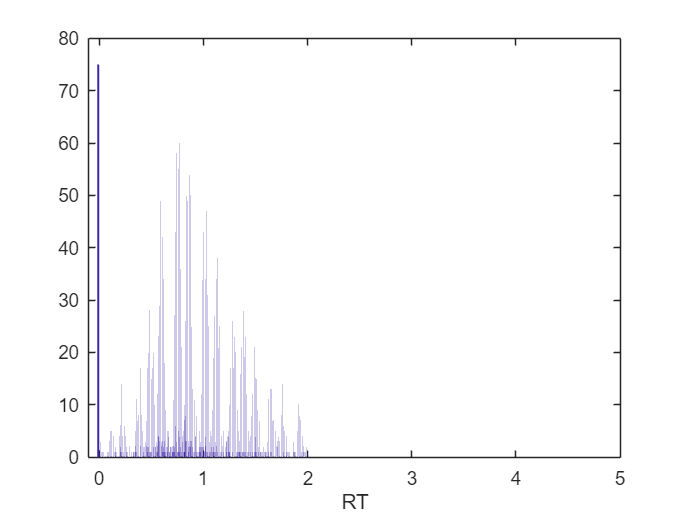

figure; hist(data_allsubj(:,3),[0:.001:5]); xlim([-0.1 5]); xlabel('RT') % note 1-ms resolution

If it's safe to count all early/wrong muscle to no response????/

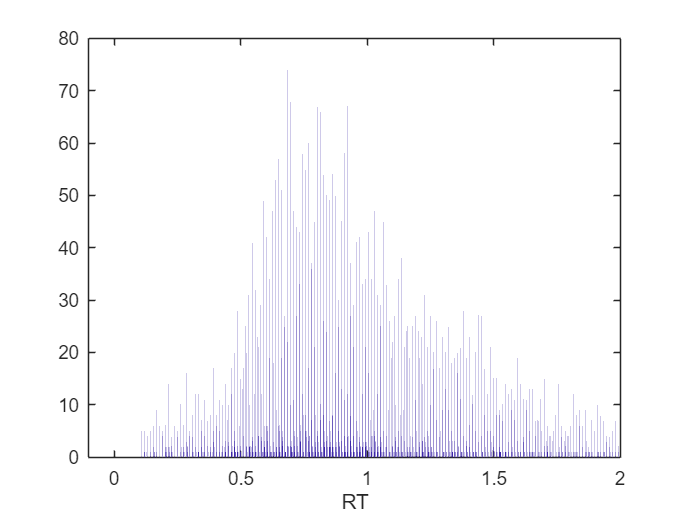

miss = find(data_allsubj(:,3)<0.1);
data_allsubj(miss,2)=2;
data_allsubj(miss,3)=nan;
figure; hist(data_allsubj(:,3),[0:.001:5]); xlim([-0.1 2]); xlabel('RT') % note 1-ms resolution

% Make the data summary:
% First define the RT quantiles from which we are going to compute the trial proportions for real and simulated data:
qps = [.1 .3 .5 .7 .9]; % these are quite standard
datsum = makeSummaryStructure(data_allsubj,qps,4); % the 4 indicates the column with a subject indicator, 

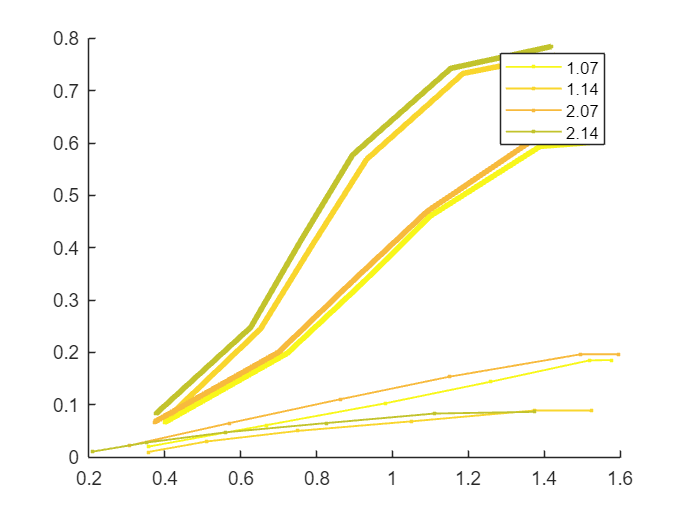

plotdatsum(datsum) % this plots a cumulative distribution, which makes it easy to see the effect of coheren e on RT and accuracy

above

%%%%% RTs are faster and the proportion correct relative to error are larger for higher coherences, as would be expected.

%%%BCP faster !!!!

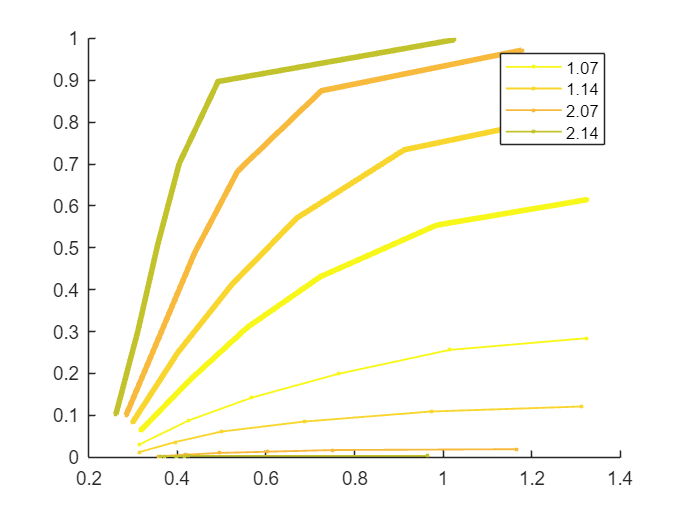

seed = sum(clock); % pick one rng seed and use it for ALL simulations to minimise the jittering about
% let's just set one drift rate for the lowest coherence and let the function scale up the rest
Sel = [1 1 0 0 0 1 1];  
pm = [0.2 0.05 0 0 0 0.08 0]; % order: [tnd d(x4) b y]
simdata = simul_2AFCddm(pm(Sel==1),pm(Sel==0),Sel,1000,seed);
simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)

above 

%not working yet

% Define parameter ranges: 
par_range = [0 0.5;... % tnd 
            0 0.5;... % d(1) drift rate for lowest coherence
            0 0.5;... % d(2) drift rate for 2nd coherence
            0 0.5;... % d(3)
            0 0.5;... % d(4)
            0 0.5;... % b bound
            -0.25 0.5]; % y bound collapse slope - allowing it to increase over time, if that's what it needs to do to fit data


modelfn = 'simul_2AFCddm'; % name of function that will be called by G2 to generate predicted data
modelnames = {'ConstBnd_1d','ConstBnd_4d','CollBnd_1d','CollBnd_4d'};
% for each, designate which will be free to vary to fit data
Selvecs = {[1 1 0 0 0 1 0], [1 1 1 1 1 1 0], [1 1 0 0 0 1 1], [1 1 1 1 1 1 1]};
pm_if_fixed = [nan nan nan nan nan nan 0]; % order: [tnd d(x4) b y] any parameter that needs to be fixed at a certain value if not free to vary? Just y=0 for const bound
N=1000; % the more trials simulated per condition, the more accurate the G^2, AIC etc, and less specific to the happenstance of the particular noise generating by the rng. Keeping it relatively low for this tutorial so doesn't take all day
tic
for m=1:length(modelnames)
    disp(modelnames{m})
    Sel = Selvecs{m};
    options = optimoptions('particleswarm','UseParallel',true, 'SwarmSize', 10*sum(Sel));
    [p,g2(m)] = particleswarm(@(p) G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,N,seed), sum(Sel), par_range((Sel==1),1)',par_range((Sel==1),2)', options);
    bestpm(m,Sel==1) = p; bestpm(m,Sel==0) = pm_if_fixed(Sel==0); 
    if all(Sel(2:5)==[1 0 0 0])
        % In the case of one free drift rate parameter,have to fill in the other drift rates:
        bestpm(m,3)=bestpm(m,2)*cohlevels(2)/cohlevels(1); bestpm(m,4)=bestpm(m,2)*cohlevels(3)/cohlevels(1); bestpm(m,5)=bestpm(m,2)*cohlevels(4)/cohlevels(1);
    end
    disp(['best parameters: ' num2str(bestpm(m,:))])
    numfreepm=sum(Sel);
    
    % Do a fresh simulation of many trials with new noise, for computing AIC/BIC:
    g2new(m) = G2(p,pm_if_fixed(Sel==0),Sel,datsum,qps,modelfn,20000,sum(clock)); % note fresh seed and 20,000 trials per condn
    AIC(m) = g2new(m) + 2*numfreepm;
    BIC(m) = g2new(m) + numfreepm*log(sum(datsum.n(:)));
end

ConstBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.29284    0.018611    0.019829    0.036005    0.037223    0.095999           0


ConstBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.32252    0.063079     0.12027    0.054714     0.13005    0.098728           0


CollBnd_1d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.41058    0.022214    0.023667    0.042975    0.044428    0.082497  -0.0080822


CollBnd_4d


Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


best parameters: 0.12459    0.067538     0.10104    0.057513     0.11148     0.16919    0.062254


toc % good to keep track of how long it takes, in case you want to explore ways of making it more efficient, e.g. increasing the step size, changing particleswarm settings

Elapsed time is 130.197331 seconds.


AIC

AIC =   320.2744  203.9174  363.1751  167.5575


BIC

BIC =   335.0688  233.5063  382.9010  202.0779


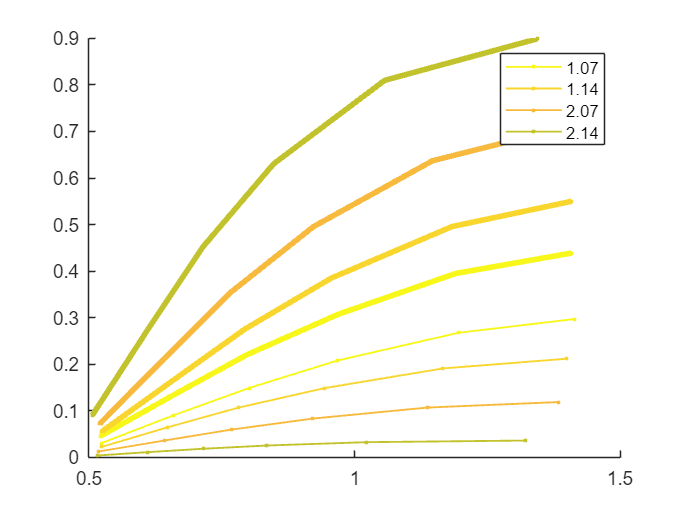

Sel = [1 1 0 0 0 1 1]; % the 3rd model for example
simdata = simul_2AFCddm(bestpm(3,Sel==1),pm_if_fixed(Sel==0),Sel,10000,seed);
simdatsum = makeSummaryStructure(simdata,qps,0);
plotdatsum(simdatsum)